# Object Oriented Programming in MATLAB

## A short walkthrough of object oriented concepts

Note: Run this section first to load the required files. This document uses audio, it is recommended to turn the volume up or use headphones.

addpath(genpath('.\lib'));

### Introduction

Object oriented programming (OOP) is a script-writing paradigm wherein we define "objects" as pertaining to a particular *class*, or *class system*, use these objects to perform subroutines and *communicate* to other objects. OOP was originally conceptualized as a mimicry of cells in a tissue, performing local tasks, hidden from the outside, and then packaging and sending messages to other cells. In the context of a computer program, we can imagine that a component of that program, an *object*, will have some characteristics, *properties*, and perform some tasks, *methods*, that only that component, and other components of that type, need. In Symphony v2+, that is precisely how a protocol *behaves*, and so it makes sense that it was developed with a OOP style.

A way I like to think of OOP is, sort of, in the context of a phylogeny: where objects are like species that belong to a phylum which *inherit* properties from their ancestors, but have novel characteristics that separate them from their ancestors.

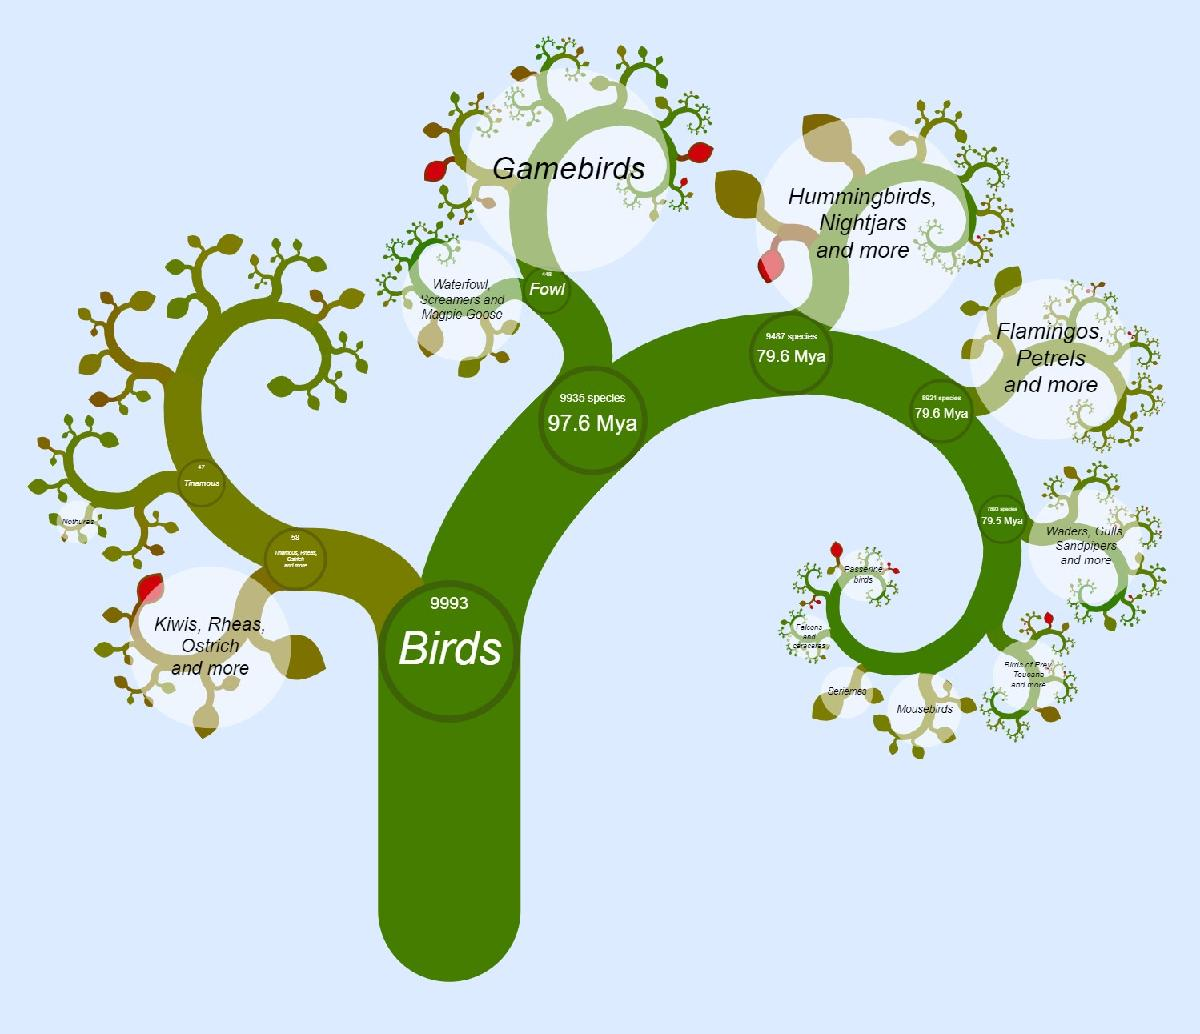

### OOP Concepts

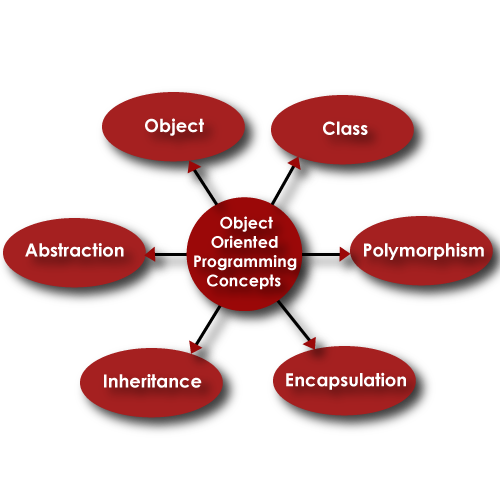

- Object: The instantiation of a component which behaves as described by its class definition.

- Class: A class is a collection of methods and properties that make up the "operating manual" of the object being defined.

- Polymorphism: The ability of a class to modify its behavior from an ancestor.

- Encapsulation: The ability of a class to hide methods and properties from public view.

- Inheritance: The properties and behaviors an object is "born" with, gained from an ancestral class.

- Abstraction: An idea of hiding the mechanism to allow complex behaviors to be performed without requiring knowledge about their underlying mechanism. A good example of abstraction is a calculator. You do not need to know how the hardware computes a logarithm to use the `log10` button.

### OOP Example

In programming, the coder is God, so we get to define the evolutionary starting point for anything. In this case, I'm going to use the California Quail (our state bird) as an example. 

If we wanted to create an ecosystem we might start with a few classes, like Animalia, Fungi, Plantae, Protozoa, etc.. but our purpose here is not to belabor the point of inheritance. So while we could separate class definitions like this:

californiaQuail < Callipepla < Phasianidae < Galliformes < Aves < Sauropsida < Tetrapoda < Gnathostomata < Vertebrata < Olfactores < Chordate < Animalia

... or something similar, let's not. You can imagine what properties each of the taxa would have and how they would be different from descendant to descendant. It's at this point that you might ask, "why? Wouldn't it just be easier to create a single function for each entity in the ecosystem?"

The short answer is: no. The long answer is: its, at worst, the same amount of work but typically, especially if you have multiple members of the same type (multiple instances), much less work. The key is in the properties.

A quick comparision of the standard vs functional vs OOP approaches:

Now, I know you're looking at that and thinking, "wait, that is way more code to make one datum with some information... what gives?!" And I would say, you're right, that is a lot of code for 1 data set. Now what about creating 2? 10? 20? what about the hundreds of epochs we produce during data acquisition?

So by being able to set properties during creation, *instantiation*, of the object, we can keep everything neat and collected without have to perform any copy-paste or manually typing many lines of code. In MATLAB, we can use builtin data types to make objects, or object-containers, by using `struct()`, `cell()`, `containers.Map()`, `table()`,` etc.`. There are some advantages and some drawbacks of using those objects in place of making your own class definitions, but that is a topic for another day.

#### Back to quails...

**Run this section by double clicking your cursor here and entering the keyboard command: Ctrl (or Cmd) + Enter

So let's start at a common entry point for our California Quail and, say, a scaled quail. These both belong to the class, Aves. More specifically, a litte ways down the phylogenetic tree, they are both Quails. We can go about creating these quails in our virtual world a number of  ways. The following is one.

So, let's define some classes to show how our oop concepts look in action. 

First, let's define our Aves ancestral class, called a *superclass*. Here we collect some properties as shown below.

As can be seen,  we have a collection of properties specific to birds with some being values we expect are inherited from a superclass that we aren't going to define (Constant) and some left without any value assigned to them. We could instantiate this object and it would exist, but it would have a bunch of empty properties and wouldn't be able to DO anything. Let's fix that.

So we know that birds, in general, can fly. Though we also know that there are some birds that can't fly, or can fly but prefer not to. Class definitions also contain behaviors, called *methods*, that control how the Aves object is going to interact with the world, i.e.  how the object sends and receives messages. Let's give our Aves a mechanism for flying and calling by defining the aptly named methods:

When we define a method, the first input argument to the method function will be a reference to the object itself, so I've given it the name, `self`. Other names you'll see, especially for MATLAB, are `obj` and  `this`. As you can see, each method uses the self reference to determine if a song exists, or if the Aves member is able to fly.

Creating a member of this class would look like:

AvesMember = Aves()

AvesMember =   Aves with properties:

    pneumaticBones: 1
     isEndothermic: 1
            canFly: []
     prefersFlight: []
              song: []
            length: []
            weight: []
          wingspan: []
         bodyColor: []
         headColor: []
         wingColor: []

And if we try to make this AvesMember fly:

AvesMember.fly()

My flight behavior isn't defined.


#### But what about quails?

**Run this section by placing your cursor here and entering the keyboard command: Ctrl (or Cmd) + Enter

You can imagine, and this is by design, that many, possibly all, birds have these properties, and so we could make thousands of birds that start with the base properties and behaviors. So let's make one: the quail.

There are probably lots of properties specific to all quails, but the first that comes to mind is the head markings. Some have tuffs others have topknots and so on. So we can, by creating a subclass of Aves called Quails, add on to our list of properties, and we can set some values for our blank properties. To do this, we need to create a special method call a *constructor*. Another feature of OOP is one where we can also override, modify or add onto superclass methods.

We have given Quails a headMarkings property, but left if blank, defined that all quails canFly = true but preferFlight = false. In order to incorporate these changes into our quail, we needed to add onto the fly method. The first line of the fly method tells MATLAB that you first want to call the method of the superclass and then run the code below. Using this object would look like:

QuailsMember = Quails()

QuailsMember =   Quails with properties:

      headMarkings: []
    pneumaticBones: 1
     isEndothermic: 1
            canFly: 1
     prefersFlight: 0
              song: []
            length: []
            weight: []
          wingspan: []
         bodyColor: []
         headColor: []
         wingColor: []

QuailsMember.fly()

I can fly!
But I'd rather walk.


As you can see, Quails can fly but prefer to walk. But if we asked for their call:

QuailsMember.call()

No call defined.


We don't have a generic quails call, mostly because quail species have very different calls from each other. Two examples of this would be the California Quail and Scaled Quail. They have descriptions that can be coded into new objects like so:

and...

This 

Thus we can have the two birds in our world:

caQuail = californiaQuail()

caQuail =   californiaQuail with properties:

      headMarkings: 'buffy crest accent'
    pneumaticBones: 1
     isEndothermic: 1
            canFly: 1
     prefersFlight: 1
              song: 'CaQuailSong.mp3'
            length: []
            weight: []
          wingspan: []
         bodyColor: 'white/black/bluish with scales'
         headColor: 'brown'
         wingColor: 'brown'

scQuail = scaledQuail()

scQuail =   scaledQuail with properties:

      headMarkings: 'comma-shaped topknot'
    pneumaticBones: 1
     isEndothermic: 1
            canFly: 1
     prefersFlight: 0
              song: 'ScQuailSong.mp3'
            length: []
            weight: []
          wingspan: []
         bodyColor: 'rich grey, brown, chestnut'
         headColor: 'black and white'
         wingColor: 'brown'

But since they have difference preferences for flight:

% Birds of a feather...
caQuail.fly()

I can fly!
Watch me take off!


scQuail.fly()

I can fly!
But I'd rather walk.


Now, what about those empty properties for length, weight and wingspan? We could set them after the fact by simply using dot notation like so:

% for the california quail
caQuail.wingspan = 15.0;
caQuail.weight = 6.7;
caQuail.length = 13;
caQuail

caQuail =   californiaQuail with properties:

      headMarkings: 'buffy crest accent'
    pneumaticBones: 1
     isEndothermic: 1
            canFly: 1
     prefersFlight: 1
              song: 'CaQuailSong.mp3'
            length: 13
            weight: 6.700000000000000
          wingspan: 15
         bodyColor: 'white/black/bluish with scales'
         headColor: 'brown'
         wingColor: 'brown'

% for teh scaled quail
scQuail.wingspan = 13.0;
scQuail.weight = 5.0;
scQuail.length = 9.5;
scQuail

scQuail =   scaledQuail with properties:

      headMarkings: 'comma-shaped topknot'
    pneumaticBones: 1
     isEndothermic: 1
            canFly: 1
     prefersFlight: 0
              song: 'ScQuailSong.mp3'
            length: 9.500000000000000
            weight: 5
          wingspan: 13
         bodyColor: 'rich grey, brown, chestnut'
         headColor: 'black and white'
         wingColor: 'brown'

It would be even better if we could provide these data at construction by implementing input agruments to the class constructor like so:

And ...

So now we can provide the information we want in the constructor of each bird, minimizing the number of lines of code needed to generate many variations of a particular quail type. So now we can create an array of california quails with different sizes, knowing that all california quails have the same coloring (assuming for the sake of the example).

CaliforniaQuailPopulation = [californiaQuail(12.5,6.5,15.2);californiaQuail(13.0,6.7,16)]

CaliforniaQuailPopulation =   2×1 californiaQuail array with properties:

    headMarkings
    pneumaticBones
    isEndothermic
    canFly
    prefersFlight
    song
    length
    weight
    wingspan
    bodyColor
    headColor
    wingColor


% view the first quail
disp(CaliforniaQuailPopulation(1))

  californiaQuail with properties:

      headMarkings: 'buffy crest accent'
    pneumaticBones: 1
     isEndothermic: 1
            canFly: 1
     prefersFlight: 1
              song: 'CaQuailSong.mp3'
            length: 12.500000000000000
            weight: 6.500000000000000
          wingspan: 15.199999999999999
         bodyColor: 'white/black/bluish with scales'
         headColor: 'brown'
         wingColor: 'brown'


Because California and Scaled Quails have different calls, but California Quails have similar (or the same for this example) calls, we can also ask the birds to sing (press the button and make sure your speakers are on):

 
CaliforniaQuailPopulation(1).call()

Listen to my call...


 
CaliforniaQuailPopulation(2).call()

Listen to my call...


 
scQuail.call();

Listen to my call...


We are able to use the fly and call methods from the Aves super, super class due to inheritance the same way we can set values in the species level class constructor for properties which have definitions in the Aves class, two super classes away. Because the Quails class adds on to the Aves class' fly method and Quails is the superclass of our species levels classes, we use the fly method without modifying it.

Can you find the in-action examples of the OOP concepts in our exercise?

What about Symphony? The next script in the series is an overview of how Symphony objects work.

All scripts used to make this presentation are available in the `lib` folder. Be sure to check them out and see the help documation at the mathworks site for more information on making your own classes: [OOP in MATLAB](https://www.mathworks.com/help/matlab/object-oriented-programming.html).

-khris (August 2019)